# Sensor Data Analysis

Input Data From Excel Sheet

clc;
clear;
close all;

% Pulling Data from Excel Sheet
% This can be done manually using Home > Import Data
% A function can also be generated using "Import Data"
[Temp, RelHum, Temp1, RelHum1, TempF, T, RH, TempAvg, HumAvg] = importfile1("/Users/admin/Documents/SensorData.xlsx", "Sheet1", [4, Inf]);


**Raw Data Plot**

The raw data can be plotted to visually inspect linearity and accuracy of data.  Individual characteristics will be more closely analyzed in later sections of code.

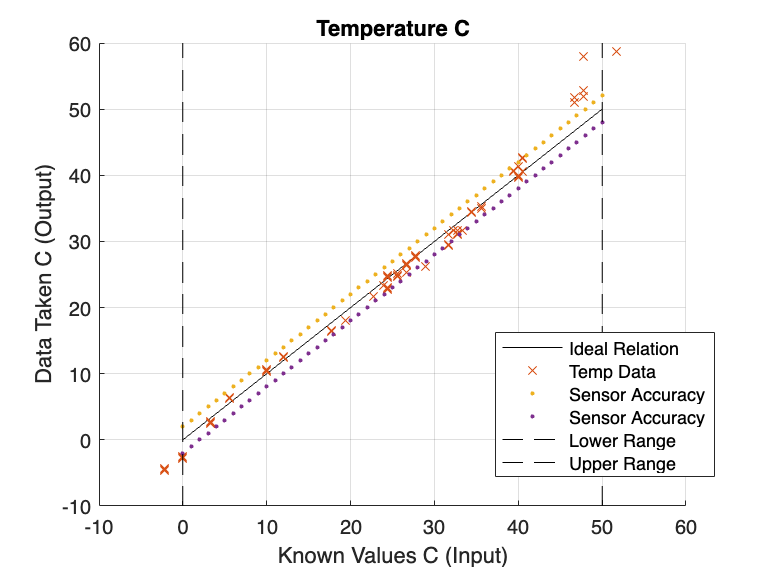

% Cleaning any NaN values from Excel Data
Ti=Temp(~isnan(Temp)); %Ti for temperature input manually
To=Temp1(~isnan(Temp1)); %To for temperature sensor output

% Plotting all temperature data
figure;
hold on

title("Temperature C")
xlabel("Known Values C (Input)")
ylabel("Data Taken C (Output)")

x=0:1:50;
y=0:1:50;
y_ep=y+2;
y_en=y-2;
plot(x,y,'k','DisplayName','Ideal Relation');
scatter(Ti,To,'x','DisplayName','Temp Data');
plot(x,y_ep,'.',x,y_en,'.','DisplayName','Sensor Accuracy');
line([0 0], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Lower Range');
line([50 50], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Upper Range'); 
legend('show')

legend("Position", [0.6996,0.17442,0.19643,0.22738])
grid on

hold off;

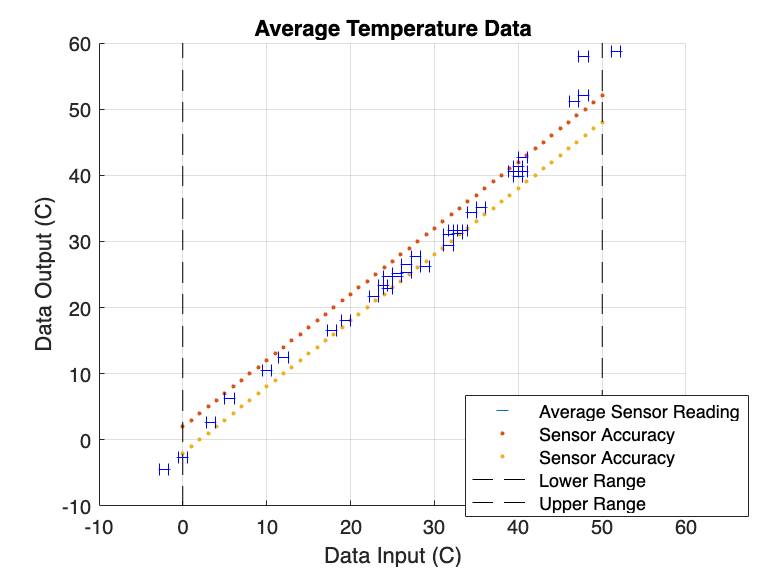

%Cleaning the Data
%removing blank values from vectors
T=T(~isnan(T));
RH=RH(~isnan(RH)); 

% Averages of data set calculated in excel and plotted here
TempAvg=TempAvg(~isnan(TempAvg));
HumAvg=HumAvg(~isnan(HumAvg));

%Plotting T vs Average Sensor Reading
figure;
hold on;

scatter(T,TempAvg,'_','DisplayName','Average Sensor Reading')
plot(x,y_ep,'.',x,y_en,'.','DisplayName','Sensor Accuracy');
line([0 0], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Lower Range');
line([50 50], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Upper Range'); 
legend('show');

% errorbar function displays uncertainty of reference sensor value based on
% half of smallest readable value of analog thermometer
errorbar(T,TempAvg,5/9,'b','horizontal','HandleVisibility', 'off');

legend("Position", [0.71548,0.15192,0.16964,0.090476])
grid on
title("Average Temperature Data")
xlabel("Data Input (C)")
ylabel("Data Output (C)")

hold off;

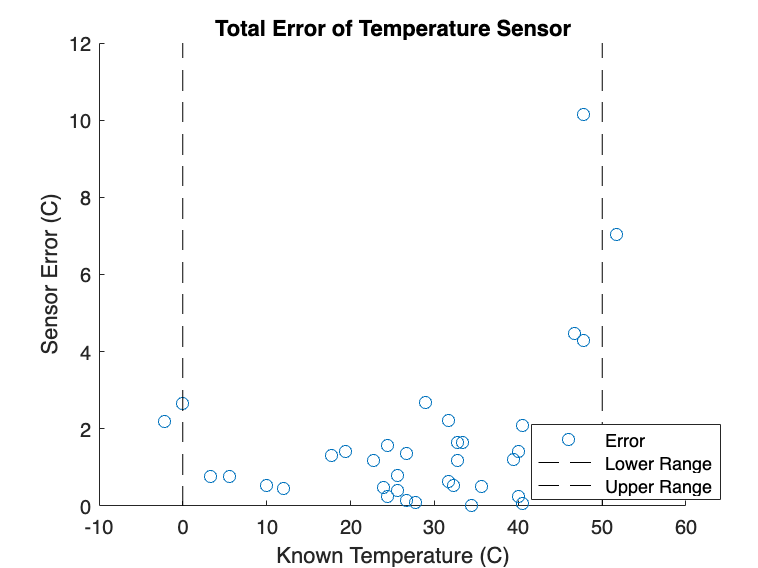



% Error vs T
% Plotting error in DHT11 sensor to visualize correlation between range and
% accuracy
figure;
hold on;
Error=abs(T-TempAvg);

scatter(T,Error,'DisplayName','Error')
line([0 0], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Lower Range');
line([50 50], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Upper Range'); 
legend('show')
title("Total Error of Temperature Sensor")
xlabel("Known Temperature (C)")
ylabel("Sensor Error (C)")
legend("Position", [0.74053,0.14172,0.16964,0.090476])
hold off;

It is observed that the error of the temperature sensor increases near and outside of its intended range.

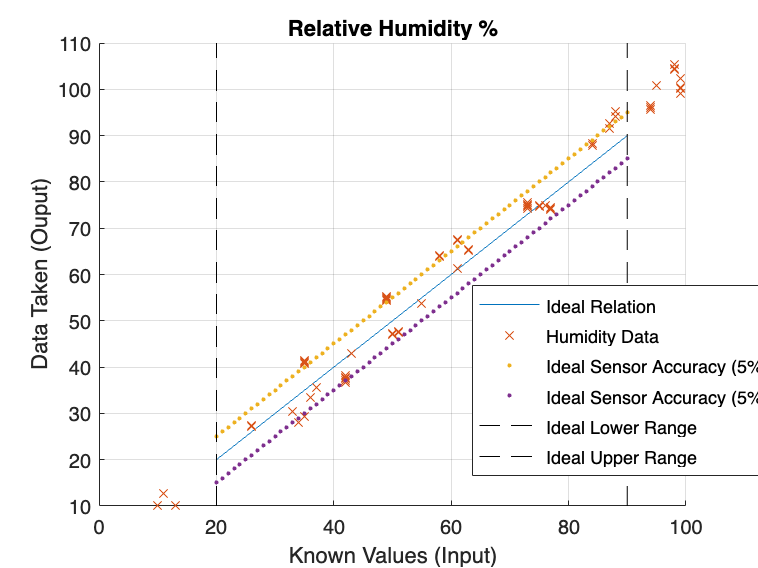

%Repeating above process for Humidity Data
Hi=RelHum(~isnan(RelHum));%Input
Ho=RelHum1(~isnan(RelHum1));%Output

figure;
hold on;

title("Relative Humidity %")
xlabel("Known Values (Input)")
ylabel("Data Taken (Ouput)")

x=20:1:90;
y=20:1:90;
x_up=1+x; %uncertainty is 1 % RH
x_un=-1+x;
y_ep=y+5;
y_en=y-5;

clear Error;

plot(x,y,'DisplayName','Ideal Relation')
scatter(Hi, Ho,'x','DisplayName','Humidity Data')
plot(x,y_ep,'.',x,y_en,'.','DisplayName','Ideal Sensor Accuracy (5%)')
line([20 20], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Lower Range');
line([90 90], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Upper Range'); 
legend('show')

legend("Position", [0.72697,0.21672,0.19643,0.22738])
grid on
hold off;

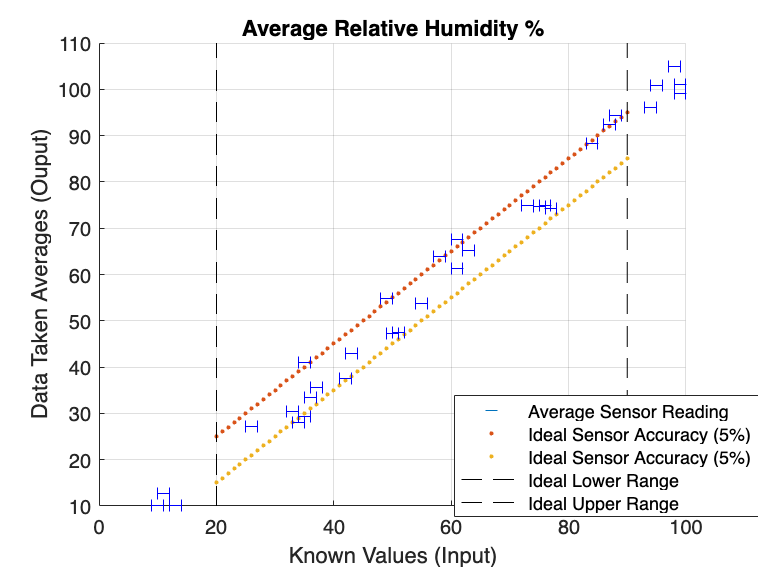

figure;

% Cleaning the Data
scatter(RH,HumAvg,'_','DisplayName','Average Sensor Reading')
title("Relative Humidity %")
xlabel("Known Values (Input)")
ylabel("Data Taken Averages (Ouput)")

hold on;
plot(x,y_ep,'.',x,y_en,'.','DisplayName','Ideal Sensor Accuracy (5%)')
line([20 20], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Lower Range');
line([90 90], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Upper Range'); 
errorbar(RH,HumAvg,1,'b','horizontal','HandleVisibility', 'off');

legend('show')
hold off;

legend("Position", [0.71548,0.15192,0.16964,0.090476])
grid on
title("Average Relative Humidity %")

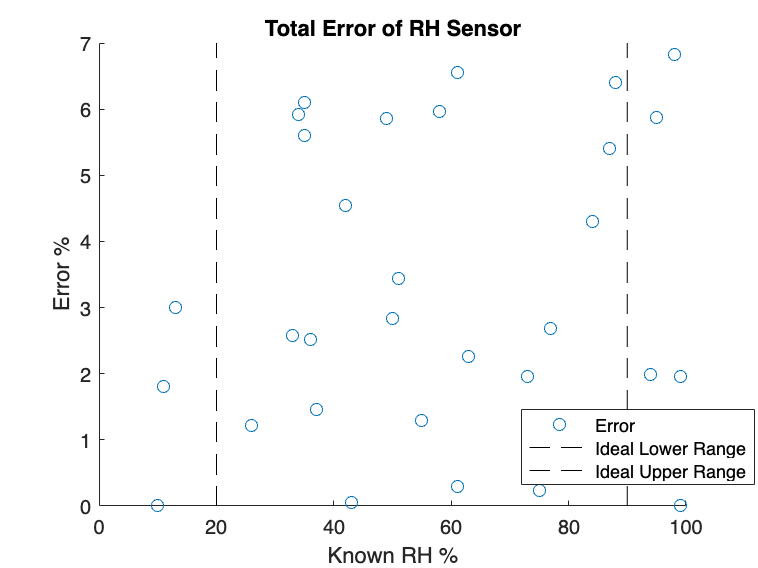

% Error vs T
Errorrh=abs(RH-HumAvg);
scatter(RH,Errorrh,'DisplayName','Error')
line([20 20], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Lower Range');
line([90 90], ylim, 'Color', 'k', 'LineStyle', '--','DisplayName','Ideal Upper Range'); 
legend('show')

title("Total Error of RH Sensor")
xlabel("Known RH %")
ylabel("Error %")

legend("Position", [0.73738,0.16709,0.20893,0.090476])

It is observed that the error of the Relative Humidity sensor is often outside of its intended accuracy range, up to 7.5 %.  The accuracy error does increase above the intended range of 90% RH.  The lower limit of range was found to be just as accurate even below the intended range, though only a few data points were taken at this range.  

**Range**

The range is defined as the lowest and highest values of the stimulus where the sensor will function within acceptable errors.

**Repeatability** 

As data is gathered at different input values, the data may vary due to lack of repeatability.  Graphed data shows that, at certain data points, the sensor reading may give two different values.  A large difference in these values may mean the sensor has low repeatability.  

**Linearity and Accuracy**

Can be observed by graphing the data and fitting a linear line.  A truly linear sensor will have an intercept at Y = 0.  

The accuracy can be determined by the error in ouput value compared to the true value.  This can be visualized by plotting the true linear function and coomparing to the experimental data's linear fit.

indicest = T >= 0 & T <= 50;

% Apply filter to input and output temperature data
filtered_T = T(indicest);
filtered_TempAvg = TempAvg(indicest);


figure;
tblt=table(filtered_T,filtered_TempAvg);
mdlt = fitlm(tblt,'filtered_T ~ filtered_TempAvg') % Adding linear fit to data plot

mdlt = Linear regression model:
    filtered_T ~ 1 + filtered_TempAvg

Estimated Coefficients:
                        Estimate       SE       tStat       pValue  
                        ________    ________    ______    __________

    (Intercept)          3.7147      0.85162    4.3619    0.00011919
    filtered_TempAvg    0.86232     0.026068    33.079    6.9616e-27


Number of observations: 35, Error degrees of freedom: 33
Root Mean Squared Error: 2.17
R-squared: 0.971,  Adjusted R-Squared: 0.97
F-statistic vs. constant model: 1.09e+03, p-value = 6.96e-27

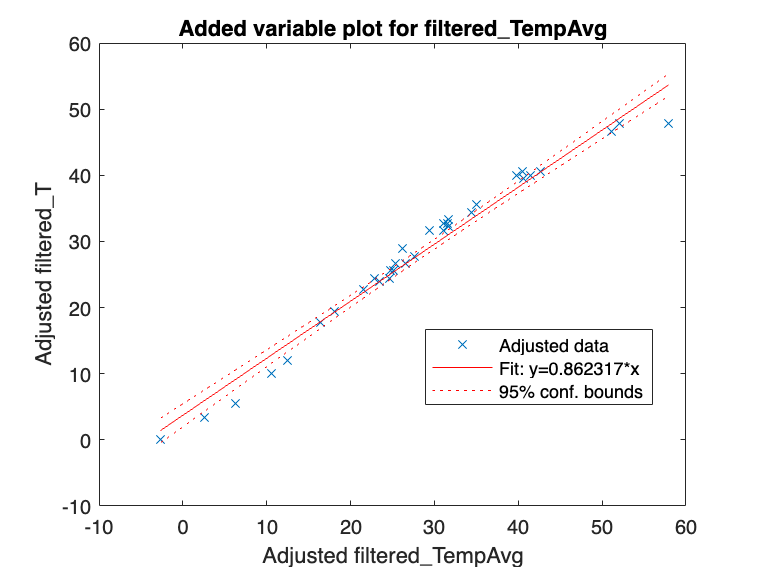

indicesh = RH >= 10 & RH <= 90;
plotAdded(mdlt)
hold off;



% Apply filter to input and output Humidity data
filtered_Hi = RH(indicesh);
filtered_Ho = HumAvg(indicesh);

figure;
tblh=table(filtered_Hi,filtered_Ho);
mdlh = fitlm(tblh,'filtered_Ho ~ filtered_Hi')

mdlh = Linear regression model:
    filtered_Ho ~ 1 + filtered_Hi

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -2.2679       1.5653    -1.4489        0.1581
    filtered_Hi     1.0581     0.028823      36.71    7.2993e-26


Number of observations: 31, Error degrees of freedom: 29
Root Mean Squared Error: 3.57
R-squared: 0.979,  Adjusted R-Squared: 0.978
F-statistic vs. constant model: 1.35e+03, p-value = 7.3e-26

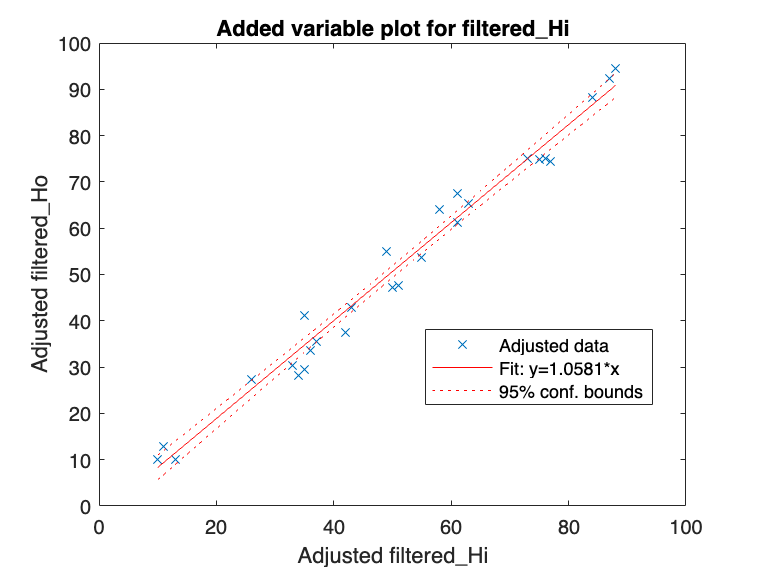

plotAdded(mdlh)
hold off;

**Sensitivity**

Determined by the change in input / change in ouput.  Theoretically, the sensitivity should be a 1 to 1 ratio for this sensor.  This is also denoted by the slope of the fitted line.  

**Resolution**

Find minimum difference between sensor values to find minimum change in data output and the resolution of the sensor.  This is the mimimum increment in stimulus to which the sensor can respond.

To_sorted=sort(To);
To_diff=diff(To_sorted);
To_res = min(To_diff(To_diff ~= 0))

To_res = 0.1000

Ho_sorted=sort(Ho);
Ho_diff=diff(Ho_sorted);
Ho_res = min(Ho_diff(Ho_diff ~= 0))

Ho_res = 0.1000